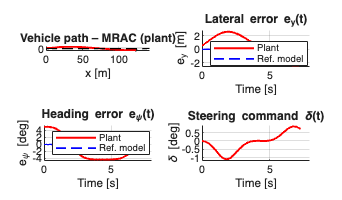

%% Ackermann MRAC – Dashboard Animation + GIF (v2)
clear; clc; close all;

%% 1. Nominal parameters (reference model)
m_nom   = 1500;
Iz_nom  = 2250;
lf      = 1.2;
lr      = 1.6;
Cf_nom  = 80e3;
Cr_nom  = 80e3;
Ux0     = 15;          % design speed

[A0, B0] = lateral_dynamics_matrix(m_nom, Iz_nom, lf, lr, Cf_nom, Cr_nom, Ux0);

% LQR for reference model
Q_lqr = diag([10, 1, 50, 10]);
R_lqr = 1;
K_des = lqr(A0, B0, Q_lqr, R_lqr);
Am    = A0 - B0*K_des;            % reference closed-loop dynamics

%% 2. True plant (moderate mismatch – you can increase later)
m_true  = 1600;
Iz_true = 2400;
Cf_true = 0.9 * Cf_nom;
Cr_true = 1.1 * Cr_nom;
Ux_true = 17;

[A_true, B_true] = lateral_dynamics_matrix(m_true, Iz_true, lf, lr, Cf_true, Cr_true, Ux_true);

%% 3. MRAC design
Qm = eye(4);
P  = lyap(Am', Qm);

Gamma    = diag([0.05, 0.05, 0.05, 0.05]);  % slow adaptation (safe)
Ba       = B0;
sigma_th = 3.0;                              % strong damping on theta

%% 4. Simulate [x; x_m; theta]
x0   = [0; 0; 0.5; 5*pi/180];    % plant initial
xm0  = zeros(4,1);               % model initial
th0  = zeros(4,1);
X0   = [x0; xm0; th0];
tspan = [0 8];

odefun = @(t, X) mrac_dynamics(t, X, A_true, B_true, Am, Ba, P, Gamma, sigma_th);
opts   = odeset('RelTol',1e-6,'AbsTol',1e-8);
[t, X] = ode15s(odefun, tspan, X0, opts);

x_hist    = X(:,1:4);        % plant
xm_hist   = X(:,5:8);        % ref model
theta_hist= X(:,9:12);

vy   = x_hist(:,1);
r    = x_hist(:,2);
ey   = x_hist(:,3);
epsi = x_hist(:,4);

ey_m   = xm_hist(:,3);
epsi_m = xm_hist(:,4);

u_hist = -sum(theta_hist .* x_hist, 2);     % u = -theta^T x

%% 5. Vehicle pose for top-down view
x_pos = Ux_true * t;
y_pos = ey;
psi   = epsi;

%% 6. Dashboard figure
fig = figure('Color','w','Position',[150 150 1200 700]);
tiledlayout(2,2);

% --- TL: path ---
nexttile(1);
hold on; grid on; axis equal;
xlabel('x [m]'); ylabel('y [m]');
title('Vehicle path – MRAC (plant)');
L = lf + lr;  W = 1.8;
body_shape = [ L/2  L/2 -L/2 -L/2 L/2;
               W/2 -W/2 -W/2  W/2 W/2];
veh_patch = patch(nan,nan,[1.0 0.5 0.3]);
traj_line = plot(nan,nan,'r-','LineWidth',1.5);
x_road = linspace(0,max(x_pos)*1.05,100);
plot(x_road,zeros(size(x_road)),'k--','LineWidth',1.0);
xlim([0 max(x_pos)*1.05]);
ylim([min(y_pos)-1, max(y_pos)+1]);

% --- TR: ey ---
nexttile(2);
hold on; grid on;
xlabel('Time [s]'); ylabel('e_y [m]');
title('Lateral error e_y(t)');
ey_plant_line = plot(nan,nan,'r-','LineWidth',1.5);
ey_model_line = plot(nan,nan,'b--','LineWidth',1.2);
legend('Plant','Ref. model','Location','best');
xlim([t(1),t(end)]);
ylim(1.1*[min([ey;ey_m]), max([ey;ey_m])] + 1e-3);

% --- BL: epsi ---
nexttile(3);
hold on; grid on;
xlabel('Time [s]'); ylabel('e_\psi [deg]');
title('Heading error e_\psi(t)');
epsi_deg   = epsi   * 180/pi;
epsi_m_deg = epsi_m * 180/pi;
epsi_plant_line = plot(nan,nan,'r-','LineWidth',1.5);
epsi_model_line = plot(nan,nan,'b--','LineWidth',1.2);
legend('Plant','Ref. model','Location','best');
xlim([t(1),t(end)]);
ylim(1.1*[min([epsi_deg;epsi_m_deg]), max([epsi_deg;epsi_m_deg])] + 1e-3);

% --- BR: delta ---
nexttile(4);
hold on; grid on;
xlabel('Time [s]'); ylabel('\delta [deg]');
title('Steering command \delta(t)');
delta_deg = u_hist * 180/pi;
delta_line = plot(nan,nan,'r-','LineWidth',1.5);
xlim([t(1),t(end)]);
ylim(1.1*[min(delta_deg), max(delta_deg)] + 1e-3);

drawnow;

%% 7. Animation + GIF
gif_name = 'MRAC_dashboard.gif';
dt_mean  = mean(diff(t));
if dt_mean <= 0, dt_mean = 0.05; end

for k = 1:length(t)
    % pose
    xk = x_pos(k);  yk = y_pos(k);  psik = psi(k);
    Rpsi = [cos(psik) -sin(psik); sin(psik) cos(psik)];
    body_xy = Rpsi * body_shape + [xk; yk];

    set(veh_patch,'XData',body_xy(1,:),'YData',body_xy(2,:));
    set(traj_line,'XData',x_pos(1:k),'YData',y_pos(1:k));

    set(ey_plant_line,'XData',t(1:k),'YData',ey(1:k));
    set(ey_model_line,'XData',t(1:k),'YData',ey_m(1:k));

    set(epsi_plant_line,'XData',t(1:k),'YData',epsi_deg(1:k));
    set(epsi_model_line,'XData',t(1:k),'YData',epsi_m_deg(1:k));

    set(delta_line,'XData',t(1:k),'YData',delta_deg(1:k));

    drawnow;

    frame = getframe(fig);
    im = frame2im(frame);
    [A,map] = rgb2ind(im,256);
    if k == 1
        imwrite(A,map,gif_name,'gif','LoopCount',inf,'DelayTime',dt_mean);
    else
        imwrite(A,map,gif_name,'gif','WriteMode','append','DelayTime',dt_mean);
    end
end


% FINAL: make sure static figure shows full curves
set(traj_line,'XData',x_pos,'YData',y_pos);
set(ey_plant_line,'XData',t,'YData',ey);
set(ey_model_line,'XData',t,'YData',ey_m);
set(epsi_plant_line,'XData',t,'YData',epsi_deg);
set(epsi_model_line,'XData',t,'YData',epsi_m_deg);
set(delta_line,'XData',t,'YData',delta_deg);
drawnow;

disp(['Saved MRAC GIF as: ', gif_name]);


%% -------- Local functions --------
function dX = mrac_dynamics(~, X, A_true, B_true, Am, Ba, P, Gamma, sigma_th)
    x  = X(1:4);
    xm = X(5:8);
    th = X(9:12);

    u = -th' * x;

    xdot  = A_true * x + B_true * u;
    xmdot = Am * xm;

    e = x - xm;
    sigma  = e' * P * Ba;
    th_dot = Gamma * x * sigma - sigma_th * th;

    dX = [xdot; xmdot; th_dot];
end

function [A,B] = lateral_dynamics_matrix(m, Iz, lf, lr, Cf, Cr, Ux)
    A = zeros(4,4); B = zeros(4,1);
    A(1,1) = (-2*Cf/Ux - 2*Cr/Ux)/m;
    A(1,2) = (-2*Cf*lf/Ux + 2*Cr*lr/Ux - m*Ux)/m;
    A(2,1) = (-2*Cf*lf/Ux + 2*Cr*lr/Ux)/Iz;
    A(2,2) = (-2*Cf*lf^2/Ux - 2*Cr*lr^2/Ux)/Iz;
    A(3,1) = 1;
    A(3,4) = Ux;
    A(4,2) = 1;
    B(1,1) = 2*Cf/m;
    B(2,1) = 2*Cf*lf/Iz;
end
